%% AUTHOR INFORMATION
% NAME: Ashwin Balagopal S
% EMAIL: ee17d200@smail.iitm.ac.in
% Code to analyse the output from ./Test_Write_Drivers

## Preface

    clear ;
    clc ;
    if( ~exist( 'globalVars', 'var' ) )
        globalVars=[];
    end
    eval( [ 'clearvars -except globalVars ' sprintf( '%s ', globalVars ) ] ) ;
    close all ;
    zeroes = @( x ) zeros( x ) ;

## Go to Global

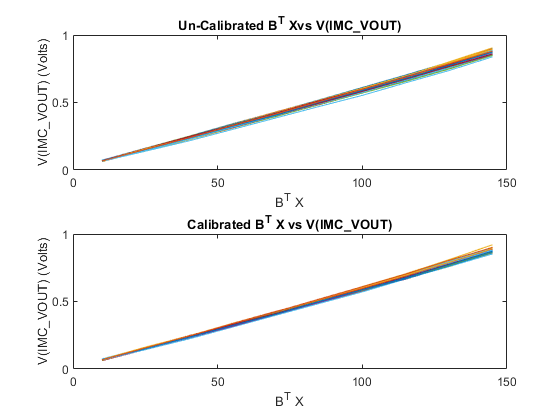

numOnesData_array=[10:15:150];
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\012_CurrentMirrorCalibration\withoutCalib_MAX_Xfers.mat');
MAC_xfers_unCalib=withoutCalib_MAX_Xfers;
subplot(2,1,1)
plot(numOnesData_array,MAC_xfers_unCalib);
title('Un-Calibrated B^T Xvs V(IMC\_VOUT)');
xlabel('B^T X');
ylabel('V(IMC\_VOUT) (Volts)');

load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\012_CurrentMirrorCalibration\withCalib_MAX_Xfers.mat');
MAC_xfers_calib=withCalib_MAX_Xfers;
subplot(2,1,2)
plot(numOnesData_array,MAC_xfers_calib);
title('Calibrated B^T X vs V(IMC\_VOUT)');
xlabel('B^T X');
ylabel('V(IMC\_VOUT) (Volts)');